# Results: Basic Psychometrics

## Housekeeping

The mat file loaded in, below, contains 1 table:

-  psychometrics: data for psychometric analyses

### Variable Definitions

- vDiff = left value- right value

- diffic = abs(left value- right value)

- chVal = chosen value

- chosen = which target was chosen (1 = left, 0 = right)

- liftRT = reaction time (target onset to center lever lift)

- monk = monkey identifier

- session = session identifier

% clear workspace
clear;close all; clc
% load in data
load BasicPsychometrics.mat

## Psychometrics

### Basic Psychometrics

#### Choice Performance

Explain choice behavior as a function of the value difference between each item.

% run mixed effects model
choice = fitglme(psychometrics,'chosen ~ vDiff + (vDiff|monk)','Distribution','Binomial')

choice = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           30046
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                3
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    chosen ~ 1 + vDiff + (1 + vDiff | monk)

Model fit statistics:
    AIC          BIC           LogLikelihood    Deviance  
    1.633e+05    1.6334e+05    -81645           1.6329e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF       pValue      Lower       Upper    
    {'(Intercept)'}        -0.11505    0.052699    -2.1832    30044    0.029032    -0.21834    -0.011758
    {'vDiff'      }          1.3733    0.014974     91.715    30044           0       1.34

% run anova on the output of the model
choiceAnova = anova(choice)

choiceAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue  
    {'(Intercept)'}        4.7662    1      30044    0.029032
    {'vDiff'      }        8411.6    1      30044           0


#### Reaction Time

Explain reaction time behavior as a function of trial difficulty

% Mixed effects model
rt = fitglme(psychometrics,'liftRT ~ diffic + (diffic|monk)','Distribution','Normal')

rt = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           30046
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                4
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    liftRT ~ 1 + diffic + (1 + diffic | monk)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -42098    -42048    21055            -42110  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE           tStat     DF       pValue        Lower        Upper  
    {'(Intercept)'}          0.88025     0.011818    74.485    30044             0      0.85708    0.90341
    {'diffic'     }        -0.032357    0.0031415     -10.3    30044    7.7602e-25    -0.038515    -0.0262

% run anova on the output of the model
rtAnova = anova(rt)

rtAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue    
    {'(Intercept)'}          5548    1      30044             0
    {'diffic'     }        106.09    1      30044    7.7602e-25


#### Number of Fixations

Explain the number of fixations per trial as a function of trial difficulty

% Mixed effects model
fix = fitglme(psychometrics,'totFix ~ diffic + (diffic|monk)')

fix = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           30046
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                4
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    totFix ~ 1 + diffic + (1 + diffic | monk)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    62449    62499    -31219           62437   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat      DF       pValue        Lower       Upper    
    {'(Intercept)'}          2.6943     0.041052     65.632    30044             0      2.6139       2.7748
    {'diffic'     }        -0.10485    0.0093161    -11.255    30044    2.5044e-29    -0.12311    -0.086593

% run anova on the output of the model
fixAnova = anova(fix)

fixAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue    
    {'(Intercept)'}        4307.5    1      30044             0
    {'diffic'     }        126.68    1      30044    2.5044e-29


#### Visualization of Results

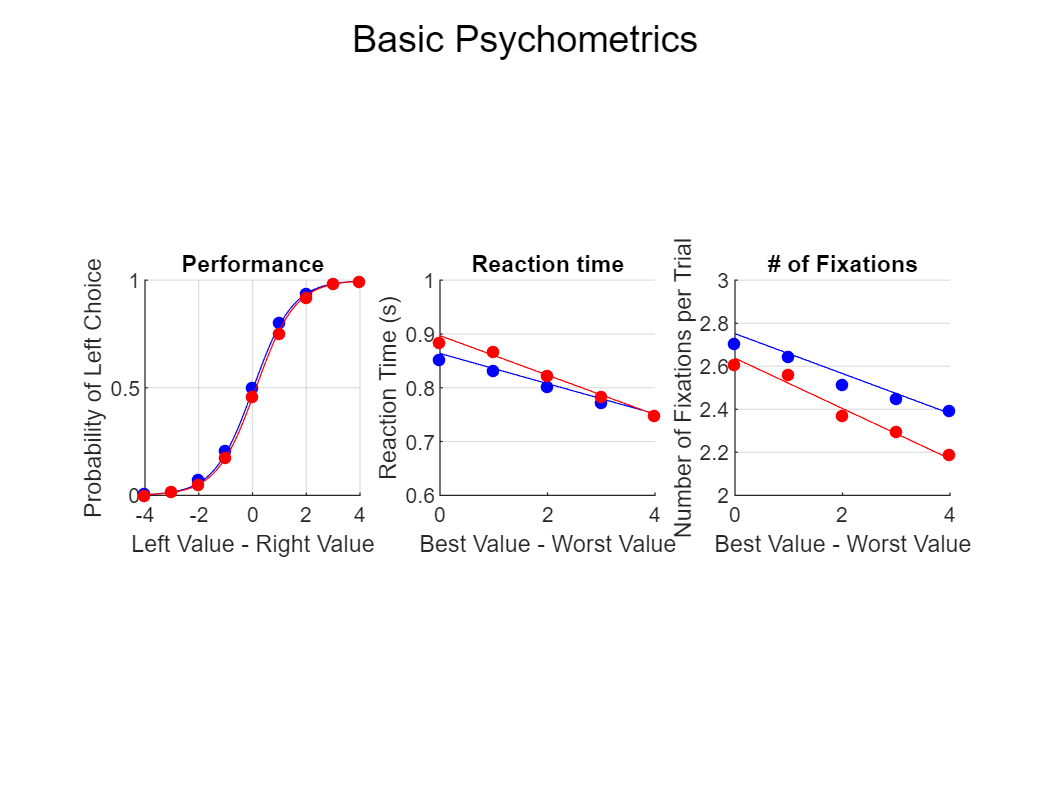

% define monk-specific variables
monks = {"MonkeyC","MonkeyK"};
colors = {'b','r'};
idx = [1:81; 82:162];
idx2 = [1:41; 42:82];

% break choice down by monk, vDiff, and session. This should generate one
% value for each session x vDiff x monk

% choice
choices = grpstats(psychometrics,{'session','vDiff','monk'},{'mean'},...
    'DataVars','chosen');

% group above stats to get 1 value for each value difference, for each monk (9x2 values total)
choices2 = grpstats(choices,{'vDiff','monk'},{'mean','sem'},...
    'DataVars',{'mean_chosen'});


rtFix = grpstats(psychometrics,{'session','diffic','monk'},{'mean'},...
    'DataVars',{'liftRT','totFix'});
rtfix2 = grpstats(rtFix,{'diffic','monk'},{'mean','sem'},...
    'DataVars',{'mean_liftRT','mean_totFix'});

% generate table table to be used for model fit line

% choice
xPred = table([-4:0.1:4]',psychometrics.totFix(1:81),psychometrics.liftRT(1:81),psychometrics.monk(1:81), psychometrics.diffic(1:81), 'VariableNames',{'vDiff','totFix','liftRT','monk','diffic'});
xPred = [xPred;xPred];
xPred.monk(82:end) = "MonkeyK";
choiceYhat = predict(choice, xPred);
xChoice = linspace(-4,4,81)';


% rt & fix
xPred2 = table([0:0.1:4]',psychometrics.totFix(1:41),psychometrics.liftRT(1:41),psychometrics.monk(1:41), psychometrics.vDiff(1:41), 'VariableNames',{'diffic','totFix','liftRT','monk','vDiff'});
xPred2 =[xPred2;xPred2];
xPred2.monk(42:end) = "MonkeyK";
rtYhat = predict(rt, xPred2);
fixYhat = predict(fix, xPred2);
xRtFix = linspace(0,4,41)';

clf
for monk = 1:2
    % choice curve
    subplot(1,3,1)
    plot(-4:4,choices2(choices2.monk == monks{monk},:).mean_mean_chosen,[colors{monk}, '.'],'MarkerSize',15); hold on 
    plot(xChoice,choiceYhat(idx(monk,:)),'color',colors{monk},'LineWidth',0.5)
    xlabel('Left Value - Right Value')
    ylabel('Probability of Left Choice')
    set(gca,'XGrid',1,'YGrid',1)
    xlim([-4 4])
    yticks([0 0.5 1])
    title('Performance')
    pbaspect([1 1 1])
    box off
    
    
    % rt curve
    subplot(1,3,2)
    plot(0:4,rtfix2(rtfix2.monk == monks{monk},:).mean_mean_liftRT,[colors{monk}, '.'],'MarkerSize',15); hold on 
    plot(xRtFix,rtYhat(idx2(monk,:)),'color',colors{monk},'LineWidth',0.5)
    ylim([0.6 1])
    xlabel('Best Value - Worst Value')
    ylabel('Reaction Time (s)')
    title('Reaction time')
    set(gca,'YGrid',1)
    pbaspect([1 1 1])
    box off
    
    % fix curve
    subplot(1,3,3)
    plot(0:4,rtfix2(rtfix2.monk == monks{monk},:).mean_mean_totFix,[colors{monk}, '.'],'MarkerSize',15); hold on 
    plot(xRtFix,fixYhat(idx2(monk,:)),'color',colors{monk},'LineWidth',0.5)
    xlabel('Best Value - Worst Value')
    ylabel('Number of Fixations per Trial')
    ylim([2 3])
    title('# of Fixations')
    yticks([2:0.2:3])
    set(gca,'YGrid',1)
    pbaspect([1 1 1])
    box off
end
sgtitle('Basic Psychometrics')

### Effects of Difficulty and Chosen Value on Reaction Times and the Number of Fixations

#### Get residuals from GLMs explaining RT using a single variable

**Difficulty**

data = psychometrics;
% glm explaining RT by difficulty
rtDiff = fitglme(data,'liftRT ~ diffic + (1+diffic |monk)');
% add residuals as variables in the table
data.diff_Resid = residuals(rtDiff);

fixDiff = fitglme(data,'totFix ~ diffic + (1+diffic |monk)');
% add residuals as variables in the table
data.diff_ResidF = residuals(fixDiff);

**Chosen Value**

% glm explaining RT by chosen value
rtChVal = fitglme(data,'liftRT ~ chVal + (1+chVal |monk)');
% add residuals as variables in the table
data.chVal_Resid = residuals(rtChVal);

% glm explaining RT by chosen value
fixChVal = fitglme(data,'totFix ~ chVal + (1+chVal |monk)');
% add residuals as variables in the table
data.chVal_ResidF = residuals(fixChVal);

#### Rerun GLMs using residualized RTs 

**Residualized over Difficulty**

rtchVal_diffResid =  fitglme(data,'diff_Resid ~ chVal + (1+chVal |monk)')

rtchVal_diffResid = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           30046
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                4
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    diff_Resid ~ 1 + chVal + (1 + chVal | monk)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -43981    -43931    21996            -43993  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat      DF       pValue        Lower        Upper    
    {'(Intercept)'}        0.097085     0.014224     6.8254    30044    8.9371e-12     0.069205      0.12497
    {'chVal'      }        -0.02632    0.0038658    -6.8082    30044    1.0066e-11   

anova(rtchVal_diffResid)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue    
    {'(Intercept)'}        46.586    1      30044    8.9371e-12
    {'chVal'      }        46.352    1      30044    1.0066e-11


fixchVal_diffResid =  fitglme(data,'diff_ResidF ~ chVal + (1+chVal |monk)')

fixchVal_diffResid = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           30046
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                4
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    diff_ResidF ~ 1 + chVal + (1 + chVal | monk)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    62208    62258    -31098           62196   

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat       DF       pValue     Lower        Upper   
    {'(Intercept)'}          0.10191     0.12582     0.80998    30044    0.41796      -0.1447     0.34852
    {'chVal'      }        -0.027703    0.034189    -0.81028    30044    0.41778    -0.094715

anova(fixchVal_diffResid)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat      DF1    DF2      pValue 
    {'(Intercept)'}        0.65607    1      30044    0.41796
    {'chVal'      }        0.65656    1      30044    0.41778


**Residualized for Chosen Value**

rtDiff_chValResid =  fitglme(data,'chVal_Resid ~ diffic + (1+diffic |monk)')

rtDiff_chValResid = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           30046
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                4
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    chVal_Resid ~ 1 + diffic + (1 + diffic | monk)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -44526    -44476    22269            -44538  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE            tStat      DF       pValue       Lower        Upper     
    {'(Intercept)'}         0.017554     0.0011875     14.782    30044    2.849e-49     0.015227      0.019882
    {'diffic'     }        -0.011012    0.00061707    -17.845    30044    7.34

anova(rtDiff_chValResid)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue   
    {'(Intercept)'}        218.51    1      30044    2.849e-49
    {'diffic'     }        318.44    1      30044    7.347e-71


fixDiff_chValResid =  fitglme(data,'chVal_ResidF ~ diffic + (1+diffic |monk)')

fixDiff_chValResid = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           30046
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                4
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    chVal_ResidF ~ 1 + diffic + (1 + diffic | monk)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    62234    62284    -31111           62222   

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF       pValue        Lower        Upper    
    {'(Intercept)'}          0.10337    0.018283      5.654    30044    1.5819e-08     0.067536      0.13921
    {'diffic'     }        -0.064834    0.011045    -5.8699    30044    4.4066e-09  

anova(fixDiff_chValResid)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue    
    {'(Intercept)'}        31.968    1      30044    1.5819e-08
    {'diffic'     }        34.456    1      30044    4.4066e-09


% rt
xPred = data(1:41,:);
xPred.chVal = [linspace(1,5,41)]';
xPred.diffic = [linspace(0,4,41)]';
xPred2 =[xPred;xPred];
xPred2.monk(42:end) = "kirby";
rtDiff_yhat = predict(rtDiff_chValResid, xPred2);
rtChVal_yhat = predict(rtchVal_diffResid, xPred2);

% fix
fixDiff_yhat = predict(fixDiff_chValResid, xPred2);
fixChVal_yhat = predict(fixchVal_diffResid, xPred2);
xDiffs = [linspace(0,4,41)'];
xChs = [linspace(1,5,41)'];
xDiffl = [linspace(0,4,82)'];
xChl = [linspace(1,5,82)'];

mfD = mean([fixDiff_yhat(1:41),fixDiff_yhat(42:end)],2);
mrD = mean([rtDiff_yhat(1:41),rtDiff_yhat(42:end)],2);
mfC = mean([fixChVal_yhat(1:41),fixDiff_yhat(42:end)],2);
mrC = mean([rtChVal_yhat(1:41),fixDiff_yhat(42:end)],2);


#### **Visualization of Results**

**Grab sessionwise means: Difficulty**

rtDiff_chResid = grpstats(data,{'session','monk','diffic'},{'mean'},...
    'DataVars',{'chVal_Resid'});

rtDiff_chResid2 = grpstats(rtDiff_chResid,{'diffic'},{'mean','sem'},...
    'DataVars',{'mean_chVal_Resid'});

fixDiff_chResid = grpstats(data,{'session','monk','diffic'},{'mean'},...
    'DataVars',{'chVal_ResidF'});

fixDiff_chResid2 = grpstats(fixDiff_chResid,{'diffic'},{'mean','sem'},...
    'DataVars',{'mean_chVal_ResidF'});


**Grab sessionwise means: Chosen Value**

rtchVal_DiffResid = grpstats(data,{'session','monk','chVal'},{'mean'},...
    'DataVars',{'diff_Resid'});

rtchVal_DiffResid2 = grpstats(rtchVal_DiffResid,{'chVal'},{'mean','sem'},...
    'DataVars',{'mean_diff_Resid'});


fixchVal_DiffResid = grpstats(data,{'session','monk','chVal'},{'mean'},...
    'DataVars',{'diff_ResidF'});

fixchVal_DiffResid2 = grpstats(fixchVal_DiffResid,{'chVal'},{'mean','sem'},...
    'DataVars',{'mean_diff_ResidF'});

rtDiff_chResid.monk = categorical(rtDiff_chResid.monk);
fixDiff_chResid.monk = categorical(fixDiff_chResid.monk);

rtchVal_DiffResid.monk  = categorical(rtchVal_DiffResid.monk);
fixchVal_DiffResid.monk = categorical(fixchVal_DiffResid.monk);

**Plot**

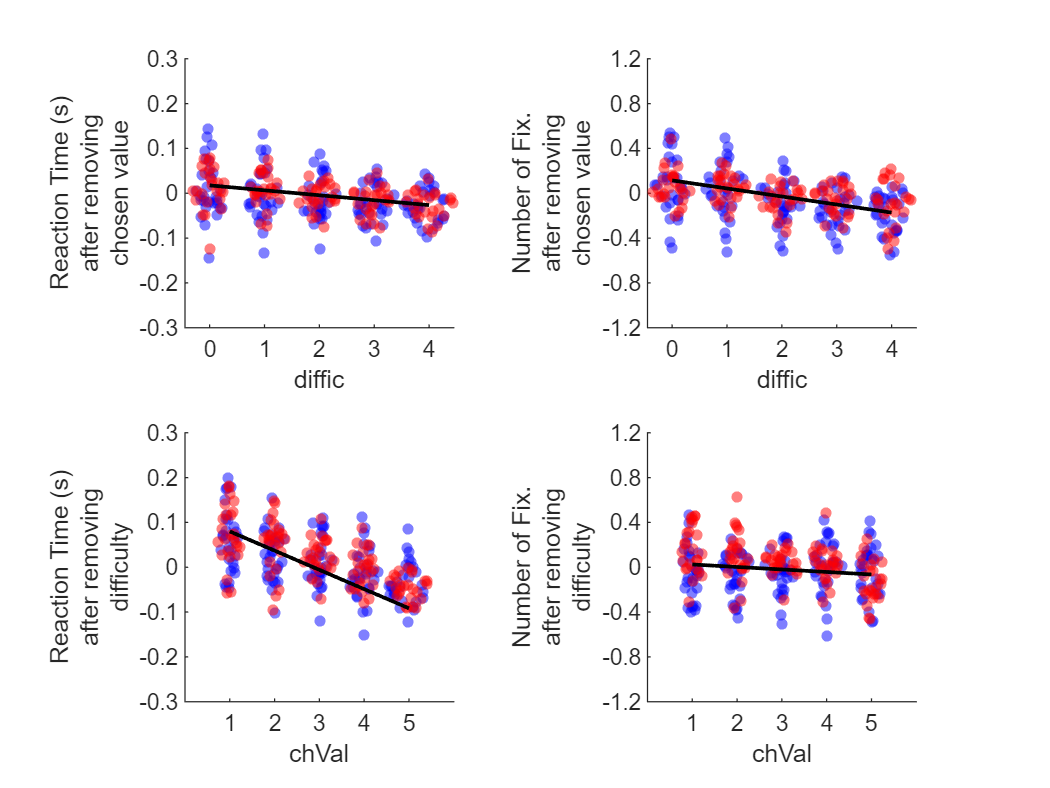

color = [repmat([0 0 255],[145 1]);repmat([255 0 0],[125 1])];
clf
subplot(2,2,1)
a = swarmchart(rtDiff_chResid,"diffic","mean_chVal_Resid",'filled','Marker','o',"CData",color,"SizeData",20,'MarkerFaceAlpha',0.5); hold on
plot(xDiffs,mrD,'k-','LineWidth',1.5);hold on
xticks(0:1:4)
pbaspect([1 1 1])
ylim([-0.3 0.3])
yticks(-0.3:0.1:0.3)
ylabel({'Reaction Time (s)', 'after removing','chosen value',})
box off


subplot(2,2,2)
swarmchart(fixDiff_chResid,"diffic","mean_chVal_ResidF",'filled','Marker','o',"CData",color,"SizeData",20,'MarkerFaceAlpha',0.5); hold on
plot(xDiffs,mfD,'k-','LineWidth',1.5);hold on
xticks(0:1:4)
pbaspect([1 1 1])
ylabel({'Number of Fix.', 'after removing','chosen value',})
box off
ylim([-1.2 1.2])
yticks(-1.2:0.4:1.2)


subplot(2,2,3)
swarmchart(rtchVal_DiffResid,"chVal","mean_diff_Resid",'filled','Marker','o',"CData",color,"SizeData",20,'MarkerFaceAlpha',0.5); hold on
plot(xChs,mrC,'k-','LineWidth',1.5);
pbaspect([1 1 1])
xticks(1:5)
ylim([-0.3 0.3])
yticks(-0.3:0.1:0.3)
ylabel({'Reaction Time (s)', 'after removing','difficulty',})
box off

subplot(2,2,4)
swarmchart(fixchVal_DiffResid,"chVal","mean_diff_ResidF",'filled','Marker','o',"CData",color,"SizeData",20,'MarkerFaceAlpha',0.5); hold on
plot(xChs,mfC,'k-','LineWidth',1.5);
pbaspect([1 1 1])
xticks(1:5)
ylim([-1.2 1.2])
yticks(-1.2:0.4:1.2)
ylabel({'Number of Fix.', 'after removing','difficulty',})